clc; clear; close all;

v = [17.4451 17.7739 19.8427 18.7536 16.3643];
f = 3000:500:5000;
k = 2*pi*f./v; 
h = 0.5549/2 * ones(size(v)) / 1000;

muestras = [1 2 4];
v = v(muestras);
f = f(muestras);
k = k(muestras);
h = h(muestras);

kh = k.*h;
% Valor inicial para fsolve
eta0 = 0.85;

% Opciones de fsolve
options = optimset('Display','off');

% Usamos arrayfun para aplicar fsolve a cada par (k(i), h(i))
eta_sol = arrayfun(@(khi) ...
    fsolve(@(eta) 4*eta.*tanh(eta*khi)./tanh(khi) - (1+eta.^2).^2, ...
           eta0, options), ...
    kh);

disp('Soluciones para eta:')

Soluciones para eta:


disp(eta_sol)

    0.9468    0.9326    0.9061



rho = 1050;

x = eta_sol.^2

x =     0.8965    0.8697    0.8209


y = rho*v.^2

y = 1.0e+05 *

    3.1955    3.3171    3.6928


% Ajuste lineal (grado 1)
p = polyfit(x, y, 1);

% Pendiente y ordenada al origen
m = p(1);
b = p(2);

disp(['Recta ajustada: y = ' num2str(m) ' * x + ' num2str(b)])

Recta ajustada: y = -671845.9033 * x + 919574.8738


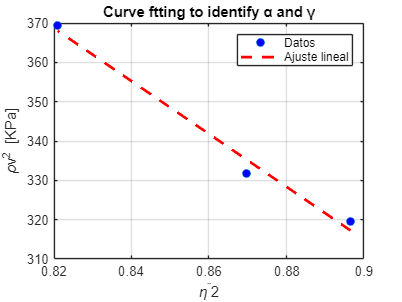


% Calcular valores ajustados
y_fit = polyval(p, x);

% Graficar
figure();
plot(x, y/1000, 'o', 'MarkerFaceColor', 'b'); hold on
plot(x, y_fit/1000, '--r', 'LineWidth', 2);
title('Curve ftting to identify α and γ')
legend('Datos', 'Ajuste lineal')
xlabel('\eta^¨2'); ylabel('\rhov^2 [KPa]');
grid on

% Resultados
alpha = b

alpha = 9.1957e+05

gamma = -m

gamma = 6.7185e+05


stress = alpha - gamma

stress = 2.4773e+05

strain = -1 + (alpha/gamma)^(1/3)

strain = 0.1103

young = stress/strain

young = 2.2460e+06